clear all;close all;
load("bonus2data_v2\wb32&26_-43&14.mat");
c = 340;
[N,nSensors] = size(X);

Perform short-time Fourier analysis on the observations. Divide the observations into different segments, and each segment is regarded as a stationary signal. Then do discrete Fourier analysis for each segment.

winlen = 512;
winmov = 256;
ms = floor((N-winlen+winmov)/winmov)+1;
Xs = zeros(ms,512,nSensors);
win = hann(512);

for i = 1:nSensors
    for j = 1:ms
        try
            Xs(j,:,i) = fft((X((1+256*(j-1)):(512+256*(j-1)),i).*win).');
        catch
        end
    end
end

Treat the same frequency band in all divisions as narrow-band and perform narrowband MUSIC algorithm in each frequency band.

n_source = 2;                                          
r = 0.035;
p = r*[cosd(-150),sind(-150),0;...
    cosd(-90),sind(-90),0;...
    cosd(-30),sind(-30),0;...
    cosd(30),sind(30),0;...
    cosd(90),sind(90),0;...
    cosd(150),sind(150),0];             

stride = 1;                                               
theta = -90:stride:90;
phi = 0:stride:90;

P_sm = zeros(length(theta),length(phi));
for k = 1:winlen/2
    tempx = squeeze(Xs(:,k,:));
    tempfs = (k-1)/512*fs;
    P_sm = P_sm + MUSIC_nb(tempx,tempfs,p,theta,phi,n_source,c);
end
P_sm = 1./P_sm;

Acquire the overall pseudo spatial spectrum, plot it, and give the DOA estimation result in the report.

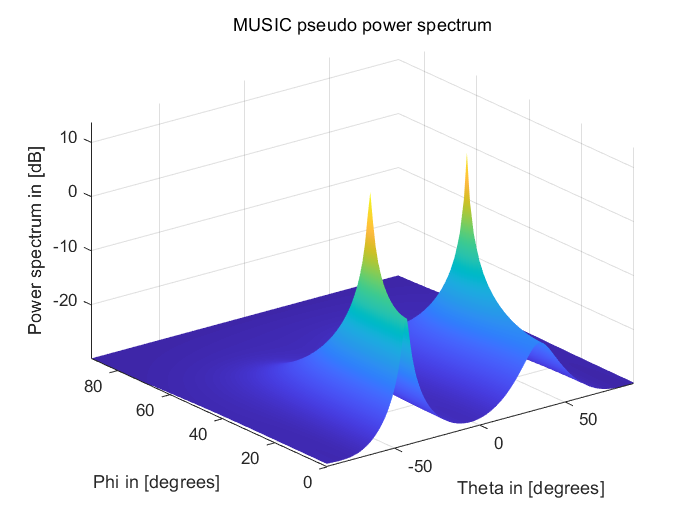

figure();
surf(theta, phi, 10*log10(abs(P_sm.')));
shading interp;
title('MUSIC pseudo power spectrum');
xlabel('Theta in [degrees]');
ylabel('Phi in [degrees]');
zlabel('Power spectrum in [dB]');
grid on; axis tight;
print('wb32&26_-43&14','-depsc','-vector');

P_local = P_sm;
[px,py] = size(P_local);
P_min = min(min(P_local));

for i = 1:px
    P = P_local(i,:).';
    P_middle = abs(P(2:end-1));
    P_front = abs(P(1:end-2));
    P_back = abs(P(3:end));
    logic_front = (P_middle - P_front)>0;
    logic_back = (P_middle - P_back)>0;
    logic = logic_front & logic_back;
    P_middle(~logic) = P_min;
    P_local(i,:) = [abs(P(1));P_middle;abs(P(end))];
end

for j = 1:py
    P = P_local(:,j);
    P_middle = abs(P(2:end-1));
    P_front = abs(P(1:end-2));
    P_back = abs(P(3:end));
    logic_front = (P_middle - P_front)>0;
    logic_back = (P_middle - P_back)>0;
    logic = logic_front & logic_back;
    P_middle(~logic) = P_min;
    P_local(:,j) = [abs(P(1));P_middle;abs(P(end))];
end

[Idxt1,Idxp1] = find(P_local==max(max(P_local)));
P_local(Idxt1,Idxp1) = 0;
[Idxt2,Idxp2] = find(P_local==max(max(P_local)));

disp(['The desired source DOA with MUSIC is: theta=',num2str(theta(Idxt1)),' deg and phi=',num2str(phi(Idxp1)),' deg']);

The desired source DOA with MUSIC is: theta=-43 deg and phi=14 deg


disp(['The interfering DOA with MUSIC is: theta=',num2str(theta(Idxt2)),' deg and phi=',num2str(phi(Idxp2)),' deg']);

The interfering DOA with MUSIC is: theta=32 deg and phi=26 deg


function P_sm = MUSIC_nb(tempx,tempfs,p,theta,phi,n_source,c)                                   
    [tempN,~] = size(tempx);
    fc = tempfs;
    R_x = (tempx.'*(tempx.')')/tempN;                                                     
    [EV,~] = eig(R_x);     
    Un = EV(:,1:end-n_source);                                   
    
    P_sm = zeros(length(theta),length(phi));
    for i = 1:length(phi)
        tphi = phi(i);
        
        v = [sind(theta)*cosd(tphi); ...
             -cosd(theta)*cosd(tphi); ...
             ones(size(theta))*sind(tphi)];
        a_theta = exp(-1j*2*pi*fc/c*p*v);
        
        P_sm(:,i) = diag(a_theta'*(Un*Un')*a_theta);
    end                
end